close all
clear all
clc

s = tf('s');

%%%% Define the parameters in the system
rho_0 = 1.2; %[kg/m^3]
b_0 = 1.42*(10^5); %[N/m^2]
c=sqrt(b_0/rho_0);
L = 0.6; %[m]
t_s= 5*(10^-4); %[sec]
tau=L/c;
z_0 = rho_0*c;
sigma = 5*10^-5; 
dx=0.002;
x= 0:dx:L; %[m]
dt=10^(-6);
t=0:dt:(6*tau);
N= 300;
K_0=b_0/dx;
M_0=rho_0*dx;
M=M_0*eye(N);

v_0 = (2/((pi^(0.25)*sqrt(3*sigma))))*(1-((t-t_s)/sigma).^(2)).*exp(-((t-t_s)/(sqrt(2)*sigma)).^(2))

v_0 =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000




%define the matrix and the vectros

J_n=full(gallery('tridiag',N,1,-2,1));
J_n(1,1)=-1;
J_n(end,end)=-1;

mat = inv(M)*K_0*J_n

mat = 1.0e+10 *

   -2.9583    2.9583         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.9583   -5.9167    2.9583         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  


F_0 = zeros(N,1);
F_0(1)=M_0*K_0;

F_L = zeros(N,1);
F_L(N)=M_0*K_0;


A= [zeros(N) eye(N)
        mat zeros(N)]

A = 1.0e+10 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    


B_0=zeros(2*N,1);
B_0(N+1:2*N,1)=inv(M)*F_0;
B_0

B_0 = 1.0e+07 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



B_L=zeros(2*N,1);
B_L(N+1:2*N,1)=inv(M)*F_L;


C_all = [eye(N) zeros(N)];

D=zeros(size(C_all,1),size(B_0,2));


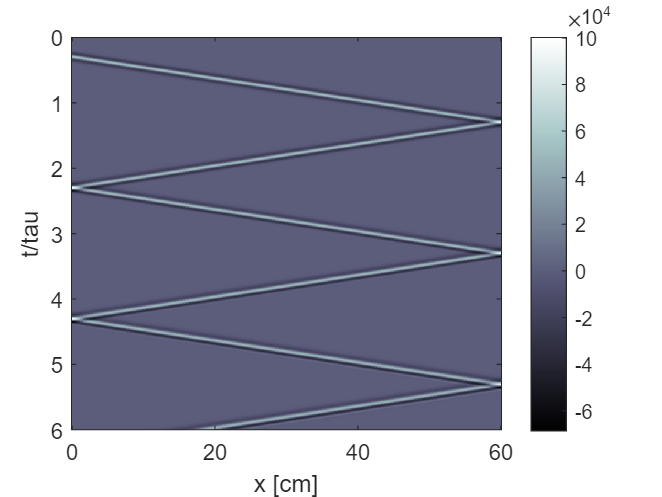

%%%%% open loop - part 1

P_0=ss(A,B_0,C_all,D);
P_L=ss(A,B_L,C_all,D);

G_ol= (P_0)*s;

P_ol=lsim(G_ol,v_0,t);

figure;
imagesc(100*x,t/tau,P_ol); colormap('bone'); colorbar;
xlabel('x [cm]');
ylabel('t/tau');

%%%%% closed loop - part 2
C_N= zeros(1,2*N);
C_N(1,N)=1

C_N =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


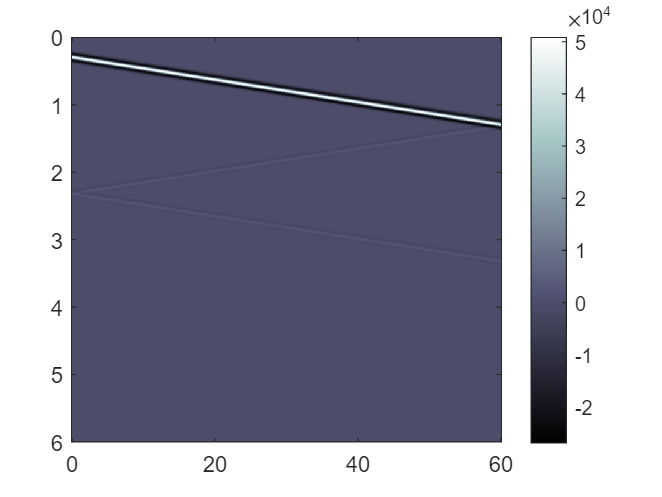


D_N=zeros(size(C_N,1),size(B_0,2));

P_0s= ss(A,B_0,C_N,D_N);
P_Ls=ss(A,B_L,C_N,D_N);

H = 1/(z_0);

P_cl = P_0*s-P_L*s*((H*P_0s*s)/(1+H*P_Ls*s));


P_CL=lsim(P_cl,v_0,t);

figure;
imagesc(100*x,t/tau,P_CL); colormap('bone'); colorbar;

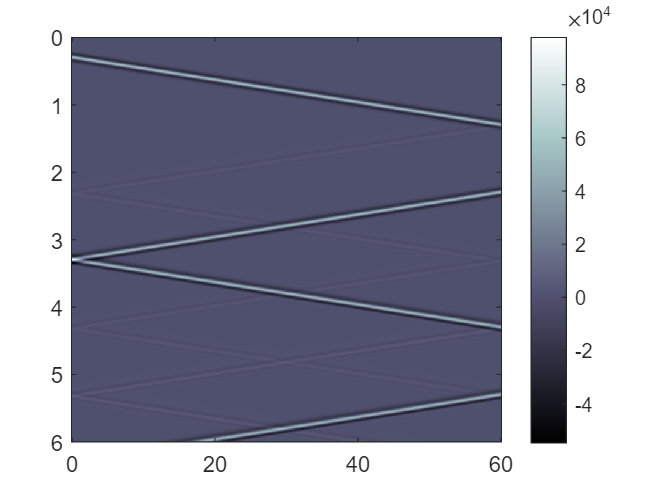

%%%%% closed loop - part 3
tau2 = 0.3/c;
H2 = (1-exp(-2*tau2*s))/(z_0*(1+exp(-2*tau2*s)));

P_cl2 = P_0*s-P_L*s*((H2*P_0s*s)/(1+H2*P_Ls*s));

P_CL2=lsim(P_cl2,v_0,t);

figure;
imagesc(100*x,t/tau,P_CL2); colormap('bone'); colorbar;